# kalman_filter.mlx

Copyright (C) 2022, Rodrigo Gonzalez, all rights reserved.

*This file is free software: you can re distribute it and/or modify it under the terms of the GNU Lesser General Public License (LGPL) version 3 as published by the Free Software Foundation. This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU Lesser General Public License for more details. You should have received a copy of the GNU Lesser General Public License along with this program. If not, see <http://www.gnu.org/licenses/>.*

- Version: 001

- Date:    2022/06/13

- Author:  Rodrigo Gonzalez <rodralez@frm.utn.edu.ar>

- URL:     https://github.com/rodralez/control

- References:  

## **INIT**

clc
clear
close all

% COLORS
blue    = [0, 0.4470, 0.7410];
orange  = [0.8500, 0.3250, 0.0980];
green   = [0.4660, 0.6740, 0.1880];
yellow  = [0.9290, 0.6940, 0.1250];
grey    = ones(1,3) * 0.65;

## INPUT VARIABLES

% Time vector, from 0 s to 10 s
dt = 0.1;
t = dt:dt:10;

% Entry voltages
u = [cos(t) * 2;
    cos(t) * 2;
    cos(t) * 2;
    cos(t) * 2
    ];

% Number of iterations
N = length(u);

## SYSTEM MATRICES

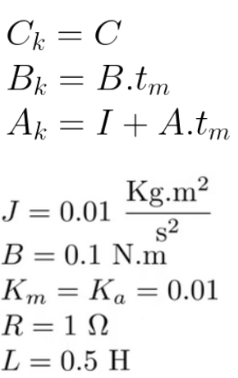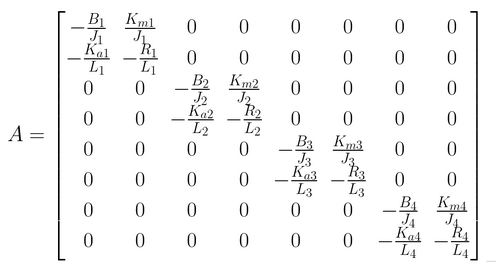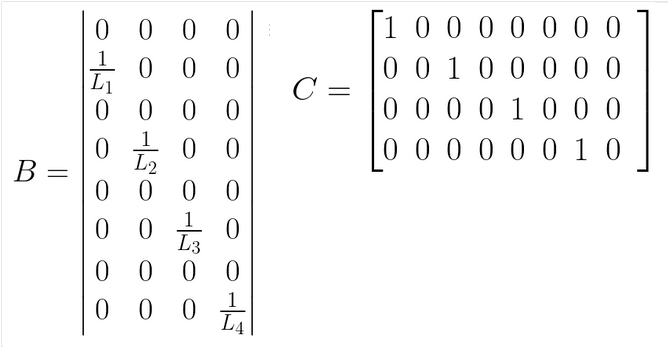

% Process model
J_motor=0.01;
B_motor=0.1;
K_motor=0.01;
R_motor=1;
L_motor=0.5;
% State transition matrix
A  = [-B_motor/J_motor K_motor/J_motor 0 0 0 0 0 0;
      -K_motor/L_motor -R_motor/L_motor 0 0 0 0 0 0;
      0 0 -B_motor/J_motor K_motor/J_motor 0 0 0 0;
      0 0 -K_motor/L_motor -R_motor/L_motor 0 0 0 0 ;
      0 0 0 0 -B_motor/J_motor K_motor/J_motor 0 0 ;
      0 0 0 0 -K_motor/L_motor -R_motor/L_motor 0 0;
      0 0 0 0 0 0 -B_motor/J_motor K_motor/J_motor ;
      0 0 0 0 0 0 -K_motor/L_motor -R_motor/L_motor];
A  = eye(8)+dt*A;
% Control-input matrix
G  = [0 0 0 0;
      1/L_motor 0 0 0;
      0 0 0 0;
      0 1/L_motor 0 0;
      0 0 0 0;
      0 0 1/L_motor 0;
      0 0 0 0;
      0 0 0 1/L_motor];
G=dt*G;

% Measurement model
% Measurement matrix
H = [ 
    1 0 0 0 0 0 0 0;
    0 0 1 0 0 0 0 0;
    0 0 0 0 1 0 0 0;
    0 0 0 0 0 0 1 0];

% Number of states
[n , ~] = size(A);

% Number of measurements
[m , ~] = size(H);

## KALMAN FILTER MATRICES

% A priori information
x_0 = [ 0 0 0 0 0 0 0 0 ]'; %assume motors were initially unenergized and stopped
P_0 = diag( [0.01 0.01 0.01 0.01 0.01 0.01 0.01 0.01].^2 );

% Process noise covariance matrix Rv
Q  = diag( (1*[0.01 0.01 0.01 0.01 0.01 0.01 0.01 0.01]).^2 );

% Process noise measurement matrix Rw
R = diag((0.5*[0.15 0.15 0.15 0.15]).^2);

## SIMULATION OF SYSTEM DYNAMICS

% Preallocation of true states 
x = zeros(N, n);
y = zeros(N, m);

% Preallocation of noisy states
x_hat = zeros(N, n);
y_hat = zeros(N, m);

% A priori states mean is zero
mu = zeros (N, n);
% States noise
x_noise = mvnrnd (mu, Q);

% A priori measurement mean is zero
mu = zeros (N, m);
% Measurement noise
y_noise = mvnrnd (mu, R);

% Init
x(1, :) = x_0;
% A priori probability distribution
x_prior =  mvnrnd(x_0, P_0)';
x_hat(1, :) = x_prior;

for i = 2:N
    % True system dynamics
    xk  = x(i-1 , :)';
    xkk = A * xk + G * u(:,i);
    yk  = H *xk ;
    x(i , :) = xkk';
    y(i , :) = yk';

    % Noisy system dynamics
    xk_n  = x_hat(i-1 , :)';
    xkk_n = A * xk_n + G * u(:,i) + x_noise(i,:)';%Warning, noise not multiplied by dt
    yk_n  = H *xk + y_noise(i,:)';                %Warning, noise not multiplied by dt
    x_hat(i , :) = xkk_n';
    y_hat(i , :) = yk_n';
end

## KALMAN FILTER IMPLEMENTATION

% Preallocation of Kalman filter states
x_til = zeros(N, n);
P_til = zeros(N, n*n);

% A priori probability distribution
[xp, Pp] = linearUpdate(x_0, P_0, y_hat(1,:)', H, R);

% Init
x_til(1 , :)  = xp;
P_til (1 , :) = reshape(Pp, 1, n*n);

for i=2:N
    % previous a posteriori state vector
    % previous a posteriori error covariance matrix
    Pp_o = reshape(P_til(i-1 , :), n , n);
    xp_o = x_til(i-1 , :)';

    % a priori state vector
    % a priori error covariance matrix
    [xi, Pi] = linearPrediction(xp_o, Pp_o, A, Q);

    % Add input force
    xi = xi + G * u(:,i) ;
    
    % a posteriori state vector
    % a posteriori error covariance matrix
    [xp, Pp] = linearUpdate(xi, Pi, y_hat(i , :)', H, R);
    
    x_til(i , :) = xp';
    P_til(i , :) = reshape(Pp, 1, n*n);
end

## KALMAN FILTER PERFORMANCE

y_err_w = rmse(y(:,1) , y_hat(:,1));
kalman_err_w = rmse(x(:,1) , x_til(:,1));

fprintf("Measurement w RMSE: %.2f rad/s \n", y_err_w)

Measurement w RMSE: 0.08 rad/s 


fprintf("Kalman w RMSE: %.2f rad/s \n", kalman_err_w)

Kalman w RMSE: 0.00 rad/s 


## PLOTS

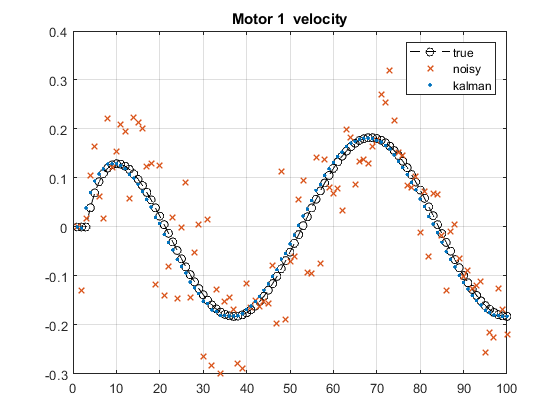

clc
close all

figure
plot(y(:,1), '--ok')
hold on
plot(y_hat(:,1), 'x', 'color', orange, 'LineWidth', 1)
plot(x_til(:,1), '.', 'color', blue, 'LineWidth', 2)
grid on
legend('true', 'noisy', 'kalman')
title('Motor 1  velocity')